**The iLQR on the cart and pole system**

Consider the cart-and-pole system here depicted:

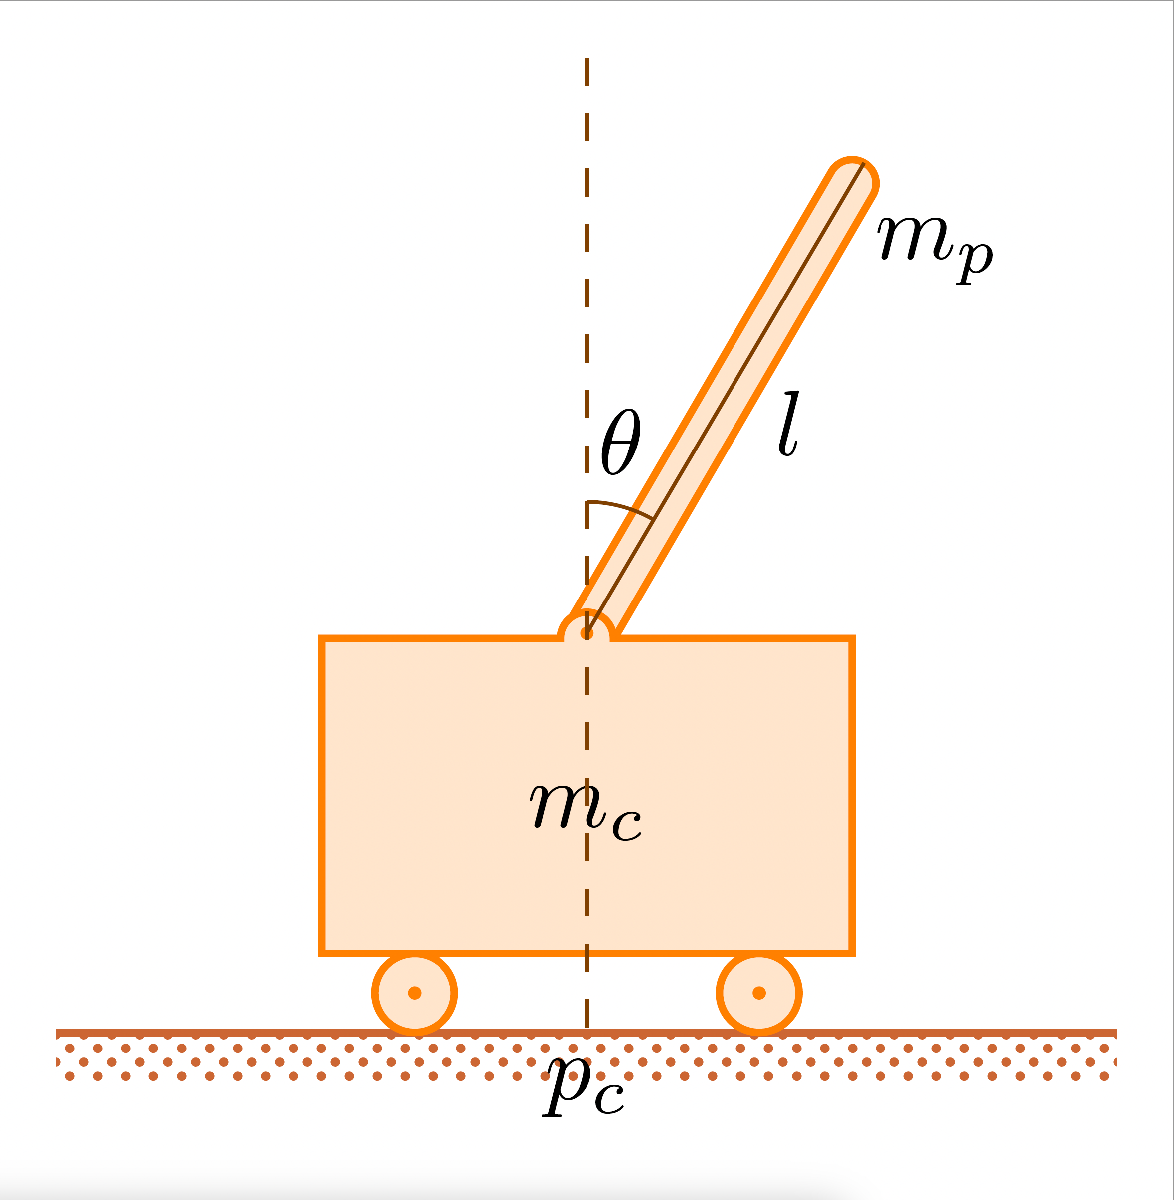

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

**INTRODUCTION**

Let's explain what we are going to do in the following exercise so that we can follow a logical thread between the theory studied and the practical application using MATLAB code.

In this HandsOn, we will deal with **Iterative LQR**, an approach that consists of *repeating the following steps* until convergence is achieved:

- Record a state-input trajectory of $H$ steps from the non-linear system

- Linearise the system around the trajectory

- Calculate the second-order Taylor series expansion of the cost around the nominal trajectory in order to obtain a quadratic approximation

- Solve the LQR problem: 

           find the solution to:


$$\underset{\pi }{\textrm{argmin}} \;\hat{x} {\left(k\right)}^T \hat{Q_H } \left(k\right)\hat{x} \left(k\right)\;\sum_{k=0}^H \hat{x} {\left(k\right)}^T \hat{Q} \left(k\right)\hat{x} \left(k\right)+\hat{u} {\left(k\right)}^T R\hat{u} \left(k\right)$$


            s.t.


$$\hat{x} \left(k+1\right)=\left\lbrack \begin{array}{cc}
A\left(k\right) & 0\\
0 & 1
\end{array}\right\rbrack \hat{x} \left(k\right)+\left\lbrack \begin{array}{c}
B\left(k\right)\\
0
\end{array}\right\rbrack \hat{u} \left(k\right)$$


            where:

$\hat{x} \left(k\right)=\left\lbrack \begin{array}{c}
x\left(k\right)-\bar{x} \left(k\right)\\
1
\end{array}\right\rbrack$     e     $\hat{u} \left(k\right)=u\left(k\right)-\bar{u} \left(k\right)$

            The solution is a controller $K_k$ that returns:


$$u\left(k\right)=-K_k \hat{x} \left(k\right)+\bar{u} \left(k\right)$$


          5. Apply the controller to the non-linear system and load a new trajectory 

              state-input of $H$ steps from the non-linear system, then repeat from step 2.

1. Simulate the non linear cart and pole system applying the provided control input sequence $\bar{u}^{(k)}$ with a sample time of 0.005 sec. Record the resulting state trajectory $\bar{x}^{(k)}$with an initial state of $\theta =180$, $\dot{\theta}=0$, $p_c=0$, $\dot{p}_c=0$. Plot the resulting trajectory.

**ANSWER 1:**

Let's simulate the behaviour of the non-linear system as in HandsOn1, but with some obvious differences:

- **the input sequence is given**, so it will not be defined randomly as in the first HandsOn.

- **the initial state is given**, so it makes no sense to consider the three different cases as in the first HandsOn, where the initial conditions had to be imposed by us.

IMPORTANT NOTE:

As in the previous HandsOn, **we will ****not**** consider the limits** imposed in the first HandsOn, since the initial conditions presented in the exercise text would already exceed the constraints we defined, and we would also have a more complex code, which is not useful for our purpose: designing an ***Iterative LQR ***(an approach that allows us to optimally control even non-linear dynamic systems, when it is not possible or appropriate to approximate the dynamics around an equilibrium point).

clear
clc
close all

% load the control input sequence
load ilqr_u.mat

% let's see what's inside
whos 

  Name               Size            Bytes  Class     Attributes

  input_traj      1001x1              8008  double              




% let's define the PHYSICAL PARAMETERS
par.g = 9.8;           % Acceleration due to gravity (m/s^2)
par.m_c = 1.0;         % Mass of the cart (kg)
par.m_p = 0.1;         % Mass of the pole (kg)
par.l = 0.5;           % Half the length of the pole (m)
par.mu_c = 0.0005;     % Cart friction
par.mu_p = 0.000002;   % Pole friction

% Let's define the SIMULATION PARAMETERS
N = 1001;             % Number of control inputs to apply   
Ts = 0.005;           % Duration of each control interval (s)
T_sim_tot = Ts*N;     % Total duration of the simulation (s)

% let's define the CONTROL INPUTS
u_seq = zeros(N,1); % Vector that will contain the input sequence

% INPUT SEQUENCE set by the exercise
u_seq(:,1) = input_traj;

% --- SIMULATION ---

% initial state imposed by the exercise
x0 = [pi; 0; 0; 0];    % [rad; rad/s; m; m/s]

% command for additional options for the ode (commented in HandsOn1)
opts = odeset('RelTol',1e-6,'AbsTol',1e-8);

% Initialisation of vectors used to save complete results
t_tot = 0:Ts:(Ts*N);
x_att = x0; 
x_tot = x_att;

% START OF SIMULATION
for k = 1:N
    % control input for the current interval
    par.F = u_seq(k);

    % we define the time interval for each iteration
    t_start = (k-1)*Ts;
    t_end = k*Ts;
    t_span = linspace(t_start, t_end);

    % we perform the simulation for the k-th segment
    [t_k, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_att, opts);

    % once the simulation is complete, we update the initial state and then move on to the next segment
    x_att = x_k(end,:)';

    % concatenate the results
    x_tot = [x_tot , x_att];
    
end

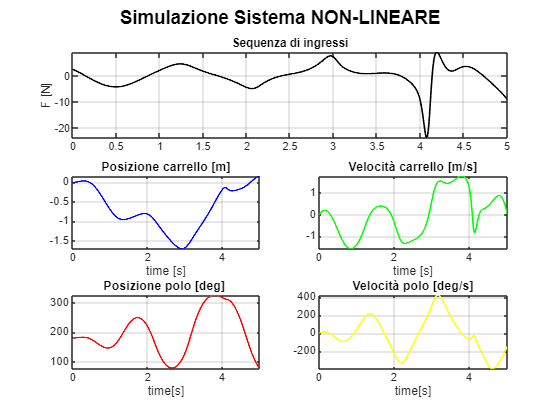

% DISPLAY OF RESULTS
figure;
sgtitle('Simulazione Sistema NON-LINEARE', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t_tot(1:N), u_seq, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Sequenza di ingressi');
grid on;

subplot(3,2,3);
plot(t_tot, x_tot(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Posizione carrello [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot, x_tot(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Velocità carrello [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot, rad2deg(x_tot(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Posizione polo [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot, rad2deg(x_tot(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Velocità polo [deg/s]');
grid on;
axis tight;


% we save the resulting trajectory obtained and the input
x_k_bar = x_tot;
u_k_bar = input_traj;

Start video recording: animation_NL ...
Video saved as: animation_NL


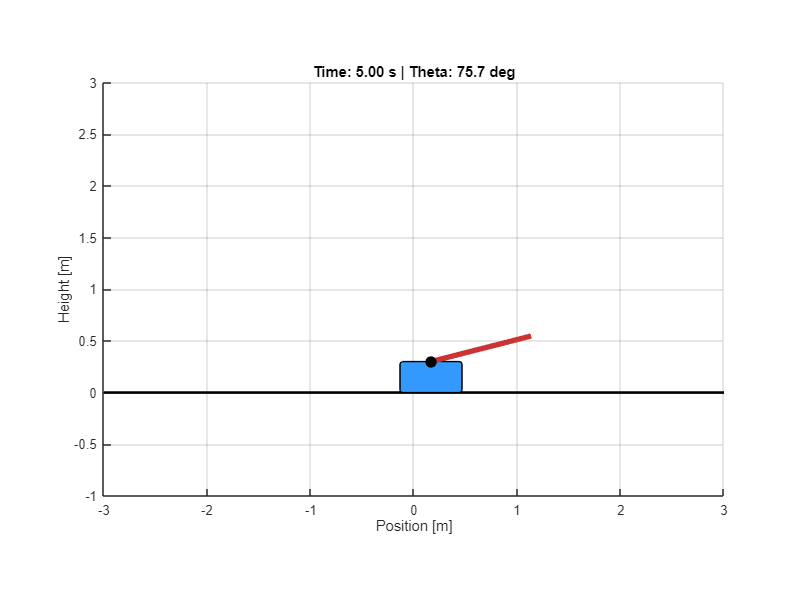

% ANIMATION OF RESULTS
animazione_test(x_tot, par, Ts, 'animation_NL')

2. Linearize the non-linear cart and pole system around the nominal state-input trajectories $\{\bar{x}^{(k)},\bar{u}^{(k)}\}$previously obtained, and store the time-varying matrices of the linearized system$\{A(k),B(k)\}$

**ANSWER 2:**

Let's linearise the non-linear cart-and-pole system just as we did in HandsOn1, but in this case we will not have an ‘equilibrium point’, but rather a "nominal state-input trajectory"  $\{\bar{x}^{(k)},\bar{u}^{(k)}\}$ that we obtained in the previous step.

% We define VARIABLES and PARAMETERS through SYMBOLIC declaration.
syms theta theta_1 p_c p_c_1 p_0
syms g m_c m_p l mu_c mu_p  F

% definition of STATE VECTOR
x = [theta ; theta_1 ; p_c ; p_c_1];

% we linearise the system around the previously obtained trajectories

% CALCULATION OF JACOBIAN MATRICES

% x = [theta ; theta_1 ; p_c ; p_c_1];
% u = F;

% let us define the state function f(x,u)

% OBS. --> for linearisation, we ignore friction (mu_c, mu_p)
%          because the sign() term is not differentiable at the origin.
theta_2_lin = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta))/(m_c+m_p))) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2_lin = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2_lin)*cos(theta)) ) / (m_c+m_p);

f = [theta_1; theta_2_lin; p_c_1; p_c_2_lin];

% we calculate the Jacobians of A_sym and B_sym
A_sym = jacobian(f, x);
B_sym = jacobian(f, F);

% REPLACEMENT OF VALUES around the NOMINAL TRAJECTORY

% nominal trajectory: x_k_bar and u_k_bar
x_bar = x_k_bar;
u_bar = u_k_bar;

% we replace the numerical values of the parameters (par)
A_num = subs(A_sym, [g, m_c, m_p, l], [par.g, par.m_c, par.m_p, par.l]);
B_num = subs(B_sym, [g, m_c, m_p, l], [par.g, par.m_c, par.m_p, par.l]);

% calculation of C and D
C = eye(4);
D = zeros(4,1);

% we define BUFFERS to save both DISCRETE numerical matrices
A_k = zeros(4,4,N);
B_k = zeros(4,1,N);

for k = 1:N
    % we replace the numerical values of the nominal trajectory (x_bar,u_bar)
    A_k(:,:,k) = double(subs(A_num, [x; F], [x_bar(:,k); u_bar(k)]));
    B_k(:,:,k) = double(subs(B_num, [x; F], [x_bar(:,k); u_bar(k)]));

    % we create an LTI system at time k
    LTI_sys_tc = ss(A_k(:,:,k), B_k(:,:,k), C, D);

    % we discretise this system at time-istant k at sampling time Ts.
    LTI_sys_td = c2d(LTI_sys_tc, Ts);

    % extract the matrices
    A_k(:,:,k) = LTI_sys_td.A;
    B_k(:,:,k) = LTI_sys_td.B;

end

3. Compute the discrete-time homogeneous representation of the linear time-varying cart and pole system obtained at point 2 and store the matrices of the homogeneous representation

**ANSWER 3:**

What are we trying to do in this exercise? We are considering a task in which, instead of minimising the state error with respect to the null state vector, we want to guide the system along a desired trajectory, while still trying to minimise the controller effort.

To apply the LQR formulation, we need to apply a transformation known as a **homogeneous transformation**, which allows us to increase the state dimension by one, thus defining the following auxiliary problem:

Find $\pi^* \left({\hat{x} }^{\left(k\right)} \right)=-K{\hat{x} }^{\left(k\right)}$ solution of:


$$\textrm{argmin}\sum_{k=0}^{H-1} {\hat{x} }^{{\left(k\right)}^T } \left\lbrack \begin{array}{cc}
Q & -q^{\left(k\right)} \\
-q^{{\left(k\right)}^T }  & d^{\left(k\right)} 
\end{array}\right\rbrack {\hat{x} }^{\left(k\right)} +u^{{\left(k\right)}^T } R\;u^{\left(k\right)}$$


s.t. ${\hat{x} }^{\left(k+1\right)} =\hat{A} {\hat{x} }^{\left(k\right)} +\hat{B} {\hat{u} }^{\left(k\right)}$

where the desired trajectory is incorporated into $q$ and $p$

% HOMOGENEOUS REPRESENTATION
n = 4; % Original state size
m = 1; % Input size

% HOMOGENEOUS MATRICES
A_h = zeros(n + 1, n + 1, N); 
B_h = zeros(n + 1, m, N);

for k = 1:N
    A_h(:,:,k) = [A_k(:,:,k), zeros(n,1); zeros(1,n), 1];
    B_h(:,:,k) = [B_k(:,:,k); zeros(1,m)];
end

4. Assume $Q=I$ and $R=1$, the cost matrices for a swing up cart and pole task, and compute $\hat{Q}(k)=$$\left\lbrack \begin{array}{cc}
Q & -{q^{\left(k\right)} }^{\top } \\
{-q}^{\left(k\right)}  & d^{\left(k\right)} 
\end{array}\right\rbrack$where $$\bar{x}^{{(k)}^\top} Q \bar{x}^{(k)}=d^{(k)}$$ and $$2\bar{x}^{{(k)}^\top} Q=2 q^{{(k)}^\top}$$for the entire nominal state trajectory  and store them

**ANSWER 4:**

Let's calculate the **second-order Taylor expansion** of the cost around the nominal trajectory in order to obtain a quadratic approximation.

What are we doing? We are trying to transform a non-linear problem, i.e. a classic real-world problem, into a Linear-Quadratic (LQR) problem. This process involves two approximations:

- **Dynamics Transformation**: we take the original non-linear system and linearise it around the nominal trajectory using the *first-order Taylor expansion (jacobians)* --> what we did in point two

- **Cost Transformation**: we take the original cost function and apply the *second-order Taylor expansion* around the nominal trajectory. This allows us to obtain a quadratic approximation of the cost --> as we will see below

% QUADRATIC COST CALCULATION
Q = eye(n);
R = 1;      

Q_h = zeros(n + 1, n + 1, N + 1);

for k = 1:N+1
    xk = x_bar(:, k);
    
    % calculation of q(k) and d(k) according to the formulas
    q_k = Q' * xk;
    d_k = xk' * Q * xk;
    
    % homogeneous cost matrix Q_hat(k)
    Q_h(:,:,k) = [Q, -q_k; -q_k', d_k];
   
end

5. Solve the finite-horizon LQR problem on the linearized version of the system and store the control gain matrices $\{K(k)\}$. Assume that $P_H =\left\lbrack \begin{array}{cc}
I & 0\\
0 & 0
\end{array}\right\rbrack$.

**ANSWER 5:**

We solve the finite-horizon LQR problem for the linearised system. The solution is obtained using ***dynamic programming***, solving the *Riccati equation* backwards in time: starting from the last time step, we calculate a sequence of gain matrices $K_k$ that minimise the quadratic cost

% --- REACHABILITY and OBSERVABILITY CHECKS ---
% OBS. --> these checks will be useful later on to determine whether the
%          assumptions for performing backward LQR are satisfied
for k = 1:N
    
    [UQ,SQ,VQ] = svd(Q); 
    Cq = UQ*SQ^.5;
    
    if (rank(ctrb(A_k(:,:,k),B_k(:,:,k)))<size(A_k(:,:,k)))
        warning("System not reachable");
        break;
    end
    
    if (rank(obsv(A_k(:,:,k),Cq))<size(A_k(:,:,k)))
        warning("System not observable");
        break;
    end

end

if k==N
    disp("The Assumptions are Satisfied");
end

The Assumptions are Satisfied



% --- LQR (in BACKWARD) ---
% let's define a buffer for the P matrices
P = zeros(n+1, n+1, N+1);

% let's save Q_h(:,:,N+1) in the last matrix
P(:,:,N+1) = Q_h(:,:,N+1);

% let's define a buffer for the gain matrices
K = zeros(m, n+1, N);

% RICCATI EQUATION (in backward)
for k = N:-1:1
    Ak = A_h(:,:,k);
    Bk = B_h(:,:,k);
    Qk = Q_h(:,:,k);

    % RICCATI EQUATION (in backward)
    P(:,:,k) = Qk+Ak'*P(:,:,k+1)*Ak-Ak'*P(:,:,k+1)*Bk*inv(R+Bk'*P(:,:,k+1)*Bk)*Bk'*P(:,:,k+1)*Ak;

    % K Gain Matrix
    K(:,:,k)=inv(R+Bk'*P(:,:,k+1)*Bk)*Bk'*P(:,:,k+1)*Ak;
end

6. Simulate the non-linear cart and pole system applying the computed control gain matrices $\{K(k)\}$ with a sample time of 0.005 sec. Record the resulting state and control input trajectory $\{\bar{x}^{(k)},\bar{u}^{(k)}\}$with an initial state of $\theta =180$, $\dot{\theta}=0$, $p_c=0$, $\dot{p}_c=0$. Plot the resulting trajectories

**ANSWER 6:**

Now we use the calculated gains $K_k$ to simulate the original non-linear system again. The input at each step will be calculated according to the feedback law:


$$u\left(k\right)=-K_k \left(x\left(k\right)-\bar{x} \right)+\bar{u}$$


This control actively corrects deviations from the nominal trajectory in an attempt to minimise the cost.

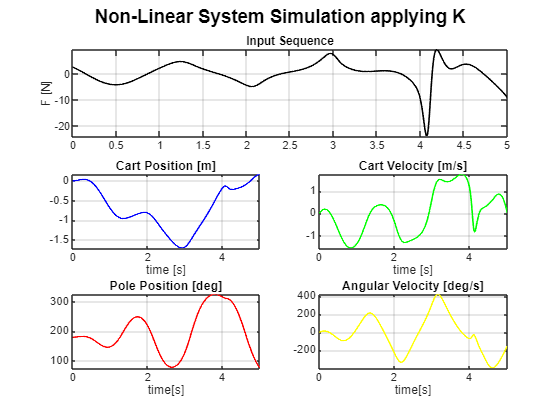

% CONTROLLED SIMULATION
x_opt = zeros(4, N + 1);
u_opt = zeros(1, N);
x_opt(:, 1) = x0; 

x_current = x0;    % let's start again from the same initial state

% START OF SIMULATION
for k = 1:N
    % Calculation of the current increased state (x(k)) and nominal state (x_bar)
    x_hat_current = [x_current; 1]; % x(k)
    x_hat_bar = [x_bar(:, k); 1];   % x_bar

    % Calculation of control input with feedback: u(k) = u_bar - K(k) * (x(k) - x_bar)
    % OBS. --> u_bar is the nominal control input trajectory,
    %          i.e. the one given in the exercise text
    u_opt(k) = u_bar(k) - K(:,:,k) * (x_hat_current - x_hat_bar);
    par.F = u_opt(k);
    
    % define time interval for each iteration
    t_start = (k-1)*Ts;
    t_end = k*Ts;
    t_span = linspace(t_start, t_end);

    % we perform the simulation for the k-th segment
    [t_k, x_sol] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_current);

    % once the simulation is complete, we update the initial state and save the result in x_opt.
    x_current = x_sol(end,:)';
    x_opt(:,k+1) = x_current;

end

% DISPLAY OF RESULTS
figure;
sgtitle('Non-Linear System Simulation applying K', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t_tot(1:N), u_opt, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t_tot, x_opt(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot, x_opt(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot, rad2deg(x_opt(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg]');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot, rad2deg(x_opt(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_NL_OPT ...
Video saved as: animation_NL_OPT


% ANIMATION OF RESULTS
animazione_test(x_opt, par, Ts, 'animation_NL_OPT')

Now let's compare the two graphs:

- the **nominal trajectory** graph (*dotted line*)

- the **optimal trajectory** graph, i.e. the one obtained by applying the gain matrices $K_k$ (*continuous line*)

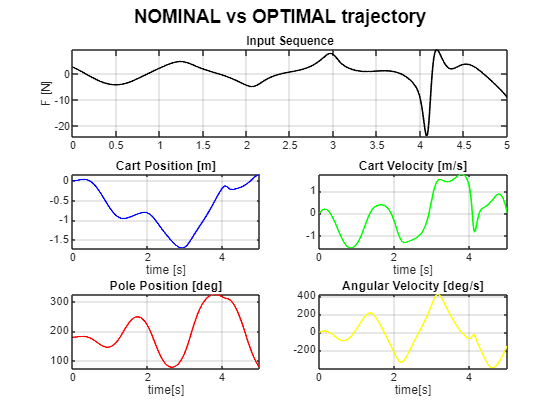

% DISPLAY THE RESULTS --> comparison between NOMINAL and OPTIMAL trajectory
figure;
sgtitle('NOMINAL vs OPTIMAL trajectory', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t_tot(1:N), u_opt, 'k', 'LineWidth', 1.2);
hold on;
plot(t_tot(1:N), u_seq, 'k--', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;

subplot(3,2,3);
plot(t_tot, x_opt(3,:), 'b', 'LineWidth', 1.2);
hold on;
plot(t_tot, x_tot(3,:), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot, x_opt(4,:), 'g', 'LineWidth', 1.2);
hold on;
plot(t_tot, x_tot(4,:), 'g--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot, rad2deg(x_opt(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t_tot, rad2deg(x_tot(1,:)), 'r--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg]');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot, rad2deg(x_opt(2,:)), 'y', 'LineWidth', 1.2);
hold on;
plot(t_tot, rad2deg(x_tot(2,:)), 'y--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

OBS.

Osservando i grafici, notiamo che la *"traiettoria ottimale"* risulta perfettamente sovrapposta alla *"traiettoria nominale"*. Questo è il comportamento che ci aspettavamo siccome la simulazione avviene in presenza dei seguenti fattori:

- **Assenza di disturbi esterni**: la simulazione avviene in un ambiente ideale, senza disturbi o incertezze.

- **Condizioni iniziali identiche**: la simulazione effettuata con le matrici di guadagno $K$, cioè la traiettoria "controllata", viene ottenuta partendo dallo stesso stato iniziale della traiettoria nominale.

- **Differenza **$\left(x\left(k\right)-\bar{x} \right)$** pari a zero nell'istante iniziale**: il controllore applica esattamente l'input nominale, quindi lo stato evolve esattamente come la traiettoria nominale, mantenendo l'errore a zero per tutta la durata della simulazione.

Pertanto ora andremo a mostrare cosa succederebbe se partissimo da condizioni iniziali perturbate. Supponiamo di avere delle condizioni iniziali pari a:


$$x_0 ={\left\lbrack \begin{array}{cccc}
170\degree  & 0 & 0 & 0
\end{array}\right\rbrack }^T$$


cioè abbiamo applicato una perturbazione di 10° sull'angolo. In tal caso dovremmo vedere la traiettoria ottimale (quella controllata dalle matrici di guadagno $K_k$ ) divergere da quella nominale per correggere l'errore:

Looking at the graphs, we notice that the *"optimal trajectory"* is perfectly superimposed on the *"nominal trajectory"*. This is the behavior we expected since the simulation occurs in the presence of the following factors:

- **Absence of external disturbances**: the simulation takes place in an ideal environment, without disturbances or uncertainties.

- **Identical initial conditions**: the simulation performed with the gain matrices $K$, i.e. the "controlled" trajectory, is obtained starting from the same initial state as the nominal trajectory.

- **Zero difference at the initial instant for **$\left(x\left(k\right)-\bar{x} \right)$: the controller applies the nominal input exactly, then the state evolves exactly like the nominal trajectory, keeping the error at zero for the duration of the simulation.

So now we will go and show what would happen if we started from perturbed initial conditions. Suppose we have initial conditions equal to:


$$x_0 ={\left\lbrack \begin{array}{cccc}
170\degree  & 0 & 0 & 0
\end{array}\right\rbrack }^T$$


that is, we applied a perturbation of 10° on the angle. In this case we should see the optimal trajectory (the one controlled by the gain matrices$K_k$) diverge from the nominal one to correct the error:

% initial state PERTURBED
x0_perturbato = [deg2rad(170); 0; 0; 0];

% CONTROLLED SIMULATION (with perturbed initial state)
x_opt_BIS = zeros(4, N + 1);
u_opt_BIS = zeros(1, N);
x_opt_BIS(:, 1) = x0_perturbato; % we start from x0 perturbed 

x_current_BIS = x0_perturbato;

% START OF SIMULATION
for k = 1:N
    % calculation of the current (x(k)) and nominal (x_bar) increased state
    x_hat_current = [x_current_BIS; 1]; % x(k)
    x_hat_bar = [x_bar(:, k); 1];       % x_bar
 
    % Calculating control input with feedback: u(k) = u_bar - K(k) * (x(k) - x_bar)
    % OBS. --> u_bar is the trajectory of the nominal control input,
    %          that is, the one given to us by the text of the exercise
    u_opt_BIS(k) = u_bar(k) - K(:,:,k) * (x_hat_current - x_hat_bar);
    par.F = u_opt_BIS(k);
    
    % we define time interval for each iteration
    t_start = (k-1)*Ts;
    t_end = k*Ts;
    t_span = linspace(t_start, t_end);

    % we run the simulation for the k-th segment
    [t_k, x_sol] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_current_BIS);

    % finished the simulation, update the initial state and save the result in x_opt
    x_current_BIS = x_sol(end,:)';
    x_opt_BIS(:,k+1) = x_current_BIS;

end

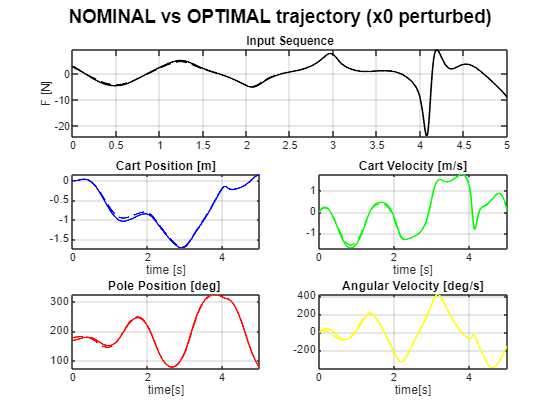

% DISPLAY OF RESULTS --> NOMINAL vs OPTIMAL trajectory comparison (x0 perturbed)
figure;
sgtitle('NOMINAL vs OPTIMAL trajectory (x0 perturbed)', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t_tot(1:N), u_opt_BIS, 'k', 'LineWidth', 1.2);
hold on;
plot(t_tot(1:N), u_seq, 'k--', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;

subplot(3,2,3);
plot(t_tot, x_opt_BIS(3,:), 'b', 'LineWidth', 1.2);
hold on;
plot(t_tot, x_tot(3,:), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot, x_opt_BIS(4,:), 'g', 'LineWidth', 1.2);
hold on;
plot(t_tot, x_tot(4,:), 'g--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot, rad2deg(x_opt_BIS(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t_tot, rad2deg(x_tot(1,:)), 'r--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot, rad2deg(x_opt_BIS(2,:)), 'y', 'LineWidth', 1.2);
hold on;
plot(t_tot, rad2deg(x_tot(2,:)), 'y--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

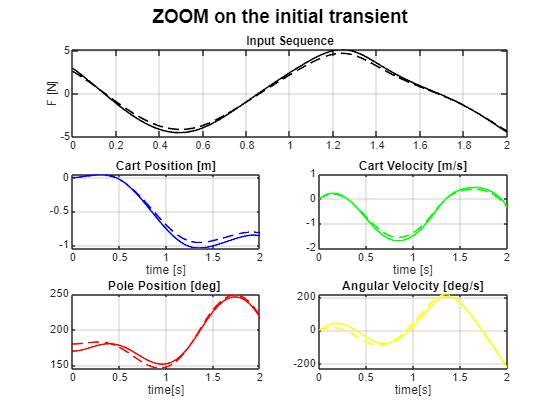

% ZOOM on the initial transient
figure;
sgtitle('ZOOM on the initial transient', 'FontWeight', 'bold');

subplot(3,2,1:2);
plot(t_tot(1:N), u_opt_BIS, 'k', 'LineWidth', 1.2);
hold on;
plot(t_tot(1:N), u_seq, 'k--', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
xlim([0 2]);

subplot(3,2,3);
plot(t_tot, x_opt_BIS(3,:), 'b', 'LineWidth', 1.2);
hold on;
plot(t_tot, x_tot(3,:), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
xlim([0 2]);

subplot(3,2,4);
plot(t_tot, x_opt_BIS(4,:), 'g', 'LineWidth', 1.2);
hold on;
plot(t_tot, x_tot(4,:), 'g--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
xlim([0 2]);

subplot(3,2,5);
plot(t_tot, rad2deg(x_opt_BIS(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t_tot, rad2deg(x_tot(1,:)), 'r--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
xlim([0 2]);

subplot(3,2,6);
plot(t_tot, rad2deg(x_opt_BIS(2,:)), 'y', 'LineWidth', 1.2);
hold on;
plot(t_tot, rad2deg(x_tot(2,:)), 'y--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
xlim([0 2]);

**FINAL OBSERVATION**

Everything we've done so far represents a single trajectory "correction", that is, a single step of the **iLQR**. As explained in the PDF corresponding to this HandsOn, to solve complex problems such as Swing-Up, that is, bringing the pole from a position of 180° to a position in a neighborhood of 0° (the text suggests a neighborhood of 20° of the center), a single correction is not enough, but as we have seen in the theory and as I reported in the introduction of this exercise, the steps from point 2 should be repeated considering as a new nominal trajectory, the optimal trajectory just found.

In conclusion, therefore, what we have achieved is only the first "tile" of an **Iterative Linear Quadratic Regulator**, the most important, since it would be enough to iterate what we presented to solve more complex problems.

**NOTE:**

*Local Functions* used in the above code, presented with appropriate comments:

% --- LOCAL FUNCTION ---
% % 1. dinamica_nonLineare() --> allows us to calculate x_dot, through the implementation
%                                of the nonlinear differential equations of the Cart-and-Pole system. 
%                                The parameters we will pass are:
%                                   - t, not used explicitly in the function, is used to call ode()
%                                   - x, state vector [4x1]
%                                   - par, a structure containing all useful parameters

function dxdt = dinamica_nonLineare(t, x, par)

% extraction of parameters and state
g = par.g;
m_c = par.m_c;
m_p = par.m_p;
l = par.l;
mu_c = par.mu_c;
mu_p = par.mu_p;
F = par.F;

theta    = x(1);
theta_1  = x(2);
p_c      = x(3);
p_c_1    = x(4);

% we therefore define theta_2 and p_c_2
theta_2 = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta)+mu_c*sign(p_c_1))/(m_c+m_p))-(mu_p*theta_1)/(m_p*l) ) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2 = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2)*cos(theta))-mu_c*sign(p_c_1) )/ (m_c+m_p);


% let's define the derivative vector dxdt
% dxdt = [theta_1; theta_2; p_c_1; p_c_2]
dxdt = zeros(4, 1);

dxdt(1) = theta_1;
dxdt(2) = theta_2;
dxdt(3) = p_c_1;
dxdt(4) = p_c_2;

end

% % 2. animazione_test() --> allows us to describe the animation of the cart-and-pole system, 
%                            thus providing visual support in addition to the graphs.
%                            It only shows the last moment in time, but this function allows us to save the various frames
%                            in a video, so that we can see the entire simulation
%                            The parameters we pass to it are:
%                               - stati, a vector containing all states 
%                               - par, a struct containing all useful parameters
%                               - Ts, sampling time
%                               - video_filename, the name we saved the video file with

function animazione_test(stati, par, Ts, video_filename)
    
    % graphical parameters
    L = 2 * par.l;          
    W_cart = 0.6;           
    H_cart = 0.3;           
    
    % let's create the figure
    h_fig = figure('Name', 'Animazione Cart-Pole', 'Color', 'w');
    set(h_fig, 'Position', [100, 100, 800, 600]); 
    clf;
    hold on;
    grid on;
    axis equal;
    xlim([-3, 3]);          
    ylim([-1, 3]); 

    % let's create the 'floor'
    line([-3, 3], [0, 0], 'Color', 'k', 'LineWidth', 2);

    % create a video file in the current folder
    v = VideoWriter(video_filename, 'MPEG-4');
    
    % OBS. --> instead of 1/Ts (which would give 200fps), we use a standard value (50), 
    %          otherwise we will have difficulty uploading the video, as well as watching it
    v.FrameRate = 50; 
    open(v);
    fprintf('Start video recording: %s ...\n', video_filename);
    
    % let's draw the Initial Condition
    theta0 = stati(1, 1);
    pos0   = stati(3, 1);
    
    % calculation of initial coordinates
    cart_x0 = pos0 - W_cart / 2;
    base_x0 = pos0;
    base_y0 = H_cart;
    punta_x0 = base_x0 + L * sin(theta0);
    punta_y0 = base_y0 + L * cos(theta0);

    % drawing stationary objects
    % OSS. --> - rectangle(), for the cart
    %          - line(), for the pole
    %          - plot(), for the joint, i.e. the junction between them
    h_cart = rectangle('Position', [cart_x0, 0, W_cart, H_cart], 'FaceColor', [0.2, 0.6, 1], 'Curvature', 0.2);
    h_pole = line([base_x0, punta_x0], [base_y0, punta_y0], 'Color', [0.8, 0.2, 0.2], 'LineWidth', 4);
    h_joint = plot(base_x0, base_y0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
    
    title_handle = title('Generazione Video in corso... ');
    xlabel('Position [m]');
    ylabel('Height [m]');
   

    % Animation Cycle
    n_steps = size(stati,2);

    for k = 1:n_steps
        
        theta = stati(1, k);
        pos   = stati(3, k);
        
        % Coordinate update
        cart_x = pos - W_cart / 2;   
        set(h_cart, 'Position', [cart_x, 0, W_cart, H_cart]);
        
        base_x = pos;
        base_y = H_cart;
        punta_x = base_x + L * sin(theta);
        punta_y = base_y + L * cos(theta);
        
        set(h_pole, 'XData', [base_x, punta_x], 'YData', [base_y, punta_y]);
        set(h_joint, 'XData', base_x, 'YData', base_y);
        
        set(title_handle, 'String', sprintf('Time: %.2f s | Theta: %.1f deg', (k-1)*Ts, rad2deg(theta)));
        
        % command for drawing the cart-and-pole
        drawnow; 
       
        % FRAME capture and frame loading (in the video)
        frame = getframe(h_fig);
        writeVideo(v, frame);
    end
    
    % Close and save the video file
    close(v);
    fprintf('Video saved as: %s\n', video_filename);
end